% Simulate supercontinuum generation for parameters similar
% to Fig.3 of Dudley et. al, RMP 78 1135 (2006)
% Written by J.C. Travers, M.H Frosz and J.M. Dudley (2009)
% Please cite this chapter in any publication using this code.
% Updates to this code are available at www.scgbook.info
% Minor bug fix: 16/03/2020

% numerical grid
n = 2^13;                   % number of grid points
twidth = 12.5e-12;          % width of time window [s]
c = 299792458;              % speed of light [m/s]
wavelength = 835e-9;        % reference wavelength [m]
w0 = (2*pi*c)/wavelength;   % reference frequency [Hz]
dt = twidth/n;
T = (-n/2:n/2 - 1).*dt; % time grid
% === input pulse
power = 10000;              % peak power of input [W]
t0 = 28.4e-15;              % duration of input [s]

% A = sqrt(power)*sech(T/t0); % input field [W^(1/2)]
% === new input pulse
q = 0.333;
Wo = 30;
L = T/t0;
J = abs(besselj(q,L));
A = sqrt(power)*exp((-(L.^2)/(Wo^2))).*J;

% === fibre parameters
flength = 0.15;             % fibre length [m]
% betas = [beta2, beta3, ...] in units [s^2/m, s^3/m ...]
betas = [-1.1830e-026, 8.1038e-041, -9.5205e-056,  2.0737e-070, ...
         -5.3943e-085,  1.3486e-099, -2.5495e-114,  3.0524e-129, ...
         -1.7140e-144];
gamma = 0.11;               % nonlinear coefficient [1/W/m]
loss = 0;                   % loss [dB/m]

% === Raman response
fr = 0.18;                  % fractional Raman contribution
tau1 = 0.0122e-12; tau2 = 0.032e-12;
RT = (tau1^2+tau2^2)/tau1/tau2^2*exp(-T/tau2).*sin(T/tau1);
RT(T<0) = 0;                % heaviside step function

% === simulation parameters
nsaves = 200;     % number of length steps to save field at

% propagate field
[Z, AT, AW, W] = gnlse(T, A, w0, gamma, betas, loss, ...
                       fr, RT, flength, nsaves);                

000.5 % complete
001.0 % complete
001.5 % complete
002.0 % complete
002.5 % complete
003.0 % complete
003.5 % complete
004.0 % complete
004.5 % complete
005.0 % complete
005.5 % complete
006.0 % complete
006.5 % complete
007.0 % complete
007.5 % complete
008.0 % complete
008.5 % complete
009.0 % complete
009.5 % complete
010.1 % complete
010.6 % complete
011.1 % complete
011.6 % complete
012.1 % complete
012.6 % complete
013.1 % complete
013.6 % complete
014.1 % complete
014.6 % complete
015.1 % complete
015.6 % complete
016.1 % complete
016.6 % complete
017.1 % complete
017.6 % complete
018.1 % complete
018.6 % complete
019.1 % complete
019.6 % complete
020.1 % complete
020.6 % complete
021.1 % complete
021.6 % complete
022.1 % complete
022.6 % complete
023.1 % complete
023.6 % complete
024.1 % complete
024.6 % complete
025.1 % complete
025.6 % complete
026.1 % complete
026.6 % complete
027.1 % complete
027.6 % complete
028.1 % complete
028.6 % complete
029.1 % complete
029.6 % comple

% === plot output
figure(1);
tlayout1 = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact'); % 2x2 gridt = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact'); % 2x2 grid

ax1 = nexttile;
WL = 2*pi*c./W; iis = (WL>450e-9 & WL<1350e-9); % wavelength grid
lIW = 10*log10(abs(AW).^2 .* 2*pi*c./WL'.^2); % log scale spectral intensity
mlIW = max(max(lIW));       % max value, for scaling plot         
pcolor(WL(iis).*1e9, Z, lIW(:,iis)); % plot as pseudocolor map
caxis([mlIW-40.0, mlIW]);  xlim([450,1350]); shading interp; 
xlabel('Wavelength / nm'); ylabel('Distance / m');

@author : slandarer


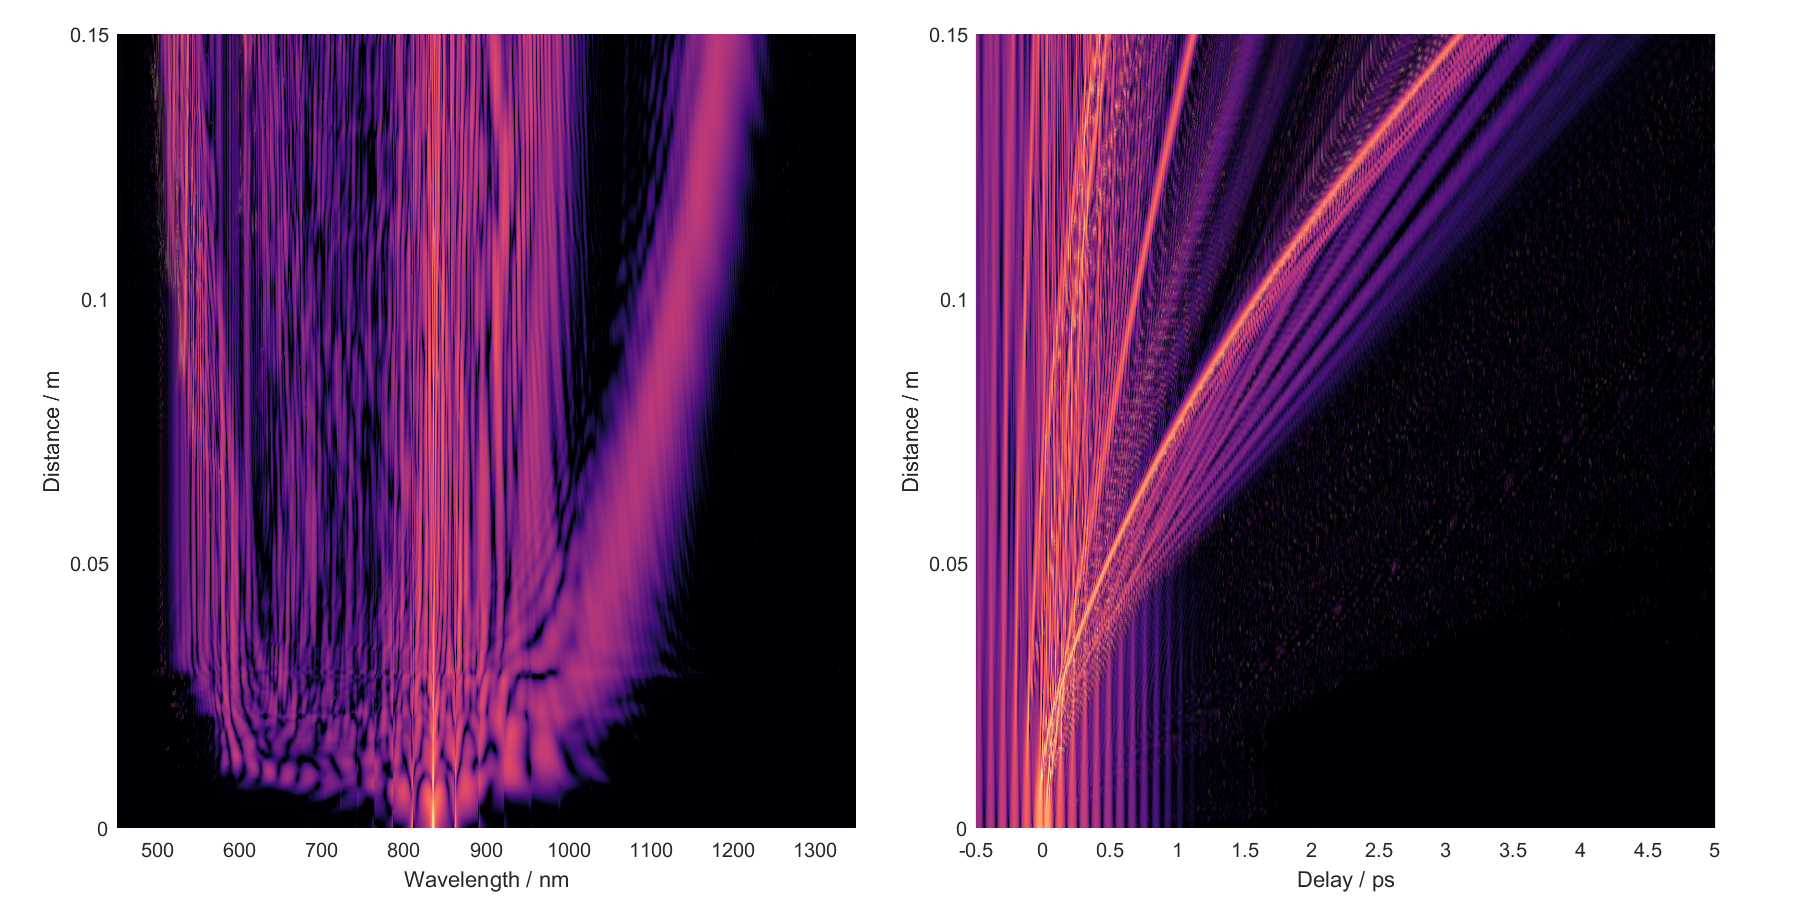

@author : slandarer



ax2 = nexttile;
lIT = 10*log10(abs(AT).^2); % log scale temporal intensity
mlIT = max(max(lIT));       % max value, for scaling plot
pcolor(T.*1e12, Z, lIT);    % plot as pseudocolor map
caxis([mlIT-40.0, mlIT]);  xlim([-0.5,5]); shading interp;
xlabel('Delay / ps'); ylabel('Distance / m');